# Exam January 11, 2019

## Exercise 1

clear
q = sym('q',[1 4])

$$q = \left(\begin{array}{cccc} q_{1} & q_{2} & q_{3} & q_{4} \end{array}\right)$$

syms d1 a4 L
dh = [ pi/2 0 d1 q(1);
       pi/2 0 0 q(2);
       pi/2 0 q(3) pi;
       0 a4 0 q(4)]

$$dh = \left(\begin{array}{cccc} \frac{\pi }{2} & 0 & d_{1} & q_{1}\\ \frac{\pi }{2} & 0 & 0 & q_{2}\\ \frac{\pi }{2} & 0 & q_{3} & \pi \\ 0 & a_{4} & 0 & q_{4} \end{array}\right)$$


[T Tpartial] = getTransformationMatrix(dh,'alpha')

$$T = \begin{array}{l} \left(\begin{array}{cccc} -\cos\left(q_{2}+q_{4}\right)\,\cos\left(q_{1}\right) & \sin\left(q_{2}+q_{4}\right)\,\cos\left(q_{1}\right) & \sin\left(q_{1}\right) & -\cos\left(q_{1}\right)\,\sigma_{1}\\ -\cos\left(q_{2}+q_{4}\right)\,\sin\left(q_{1}\right) & \sin\left(q_{2}+q_{4}\right)\,\sin\left(q_{1}\right) & -\cos\left(q_{1}\right) & -\sin\left(q_{1}\right)\,\sigma_{1}\\ -\sin\left(q_{2}+q_{4}\right) & -\cos\left(q_{2}+q_{4}\right) & 0 & d_{1}-a_{4}\,\sin\left(q_{2}+q_{4}\right)-q_{3}\,\cos\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{4}\,\cos\left(q_{2}+q_{4}\right)-q_{3}\,\sin\left(q_{2}\right) \end{array}$$

Tpartial = 1×4 cell array
    {4×4 sym}    {4×4 sym}    {4×4 sym}    {4×4 sym}



P = T(1:3,4)

$$P = \left(\begin{array}{c} -\cos\left(q_{1}\right)\,\left(a_{4}\,\cos\left(q_{2}+q_{4}\right)-q_{3}\,\sin\left(q_{2}\right)\right)\\ -\sin\left(q_{1}\right)\,\left(a_{4}\,\cos\left(q_{2}+q_{4}\right)-q_{3}\,\sin\left(q_{2}\right)\right)\\ d_{1}-a_{4}\,\sin\left(q_{2}+q_{4}\right)-q_{3}\,\cos\left(q_{2}\right) \end{array}\right)$$

q0 = [0  pi/2 L 0]

$$q0 = \left(\begin{array}{cccc} 0 & \frac{\pi }{2} & L & 0 \end{array}\right)$$

P4_0 = subs(P,q,q0)

$$P4\_0 = \left(\begin{array}{c} L\\ 0\\ d_{1}-a_{4} \end{array}\right)$$

close all
% Lengths just to test
len = 20

len = 20

len1 = 10

len1 = 10

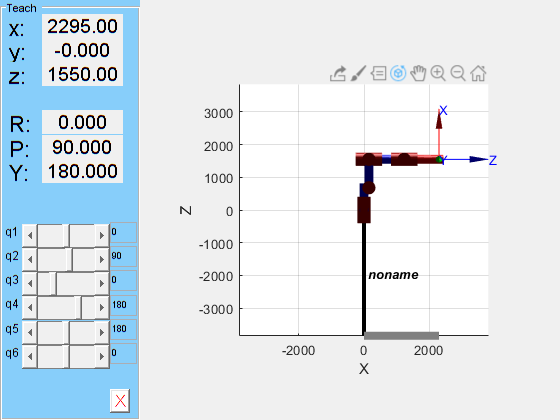

% De Luca's approach
links = [
    Revolute('alpha', pi/2, 'a', 150 ,'d', 680,'qlim', [-pi pi]);
    Revolute('alpha', 0, 'a',870 ,'d', 0,'qlim', [-50*pi/180, 195*pi/180]);
%     Prismatic('qlim', [0 len1],'alpha',pi/2,'theta',pi);
    Revolute('alpha', pi/2, 'a',0 ,'d', 0,'qlim', [-65*pi/180, 225*pi/180]);
    Revolute('alpha', pi/2, 'a',0 ,'d',1080,'qlim', [-360*pi/180, 360*pi/180]);
    Revolute('alpha', pi/2, 'a',0 ,'d',0,'qlim', [35*pi/180, 325*pi/180]);
    Revolute('alpha', 0, 'a',0 ,'d',1065,'qlim', [-360*pi/180, 360*pi/180]);

    ];

c600 = SerialLink(links);
c600.teach([0 , pi/2,0,pi,pi,0],'view','x')

% c600.plot([0,0],'view','x')
figure

% % My original approach --> Not the same result
% close all
% len = 20
% len1 = 10
% links = [
%     Revolute('a', 0, 'alpha', pi/2 ,'d', len1);
%     Revolute('a', 0, 'alpha', -pi/2 ,'d', 0);
%     Prismatic('qlim', [0 len],'alpha',pi/2,'theta',0);
%     Revolute('a', len1, 'alpha', 0 ,'d', 0);
%     ];
% 
% c600 = SerialLink(links);
% c600.teach([0  pi/2 10 0],'view','x')
% %c600.plot([0  pi/2 10 0],'view','x')

## Exercise 2

% [Jp Jo] = getJacobian(dh,'RRPR','alpha')
% 
% rank(Jo)
% %The generic rank of the lower Jac matrix is 2
% J = [Jp;Jo];
% J0 = subs(J,q,q0)
% Jp0 = subs(Jp,q,q0)

% qdot = sym('q',[4,1])
% JpQdot = Jp0*qdot
% [qdot01 qdot02 qdot03 qdot04] = solve(JpQdot == 0,qdot)

% v1 = [1 0 1];
% w1 = [0 0 -2];
% V = [v1  w1]
% 
% [qdot1 qdot2 qdot3 qdot4] = solve(JpQdot == v1.')
% null(JpQdot-v1)
% %It is not possible to satisfy both v and w conditions
% [qdot1 qdot2 qdot3 qdot4] = solve(J0*qdot == V)

% J0.'
% tau = J0.'*Fc

% null(J0.')

## Exercise 3

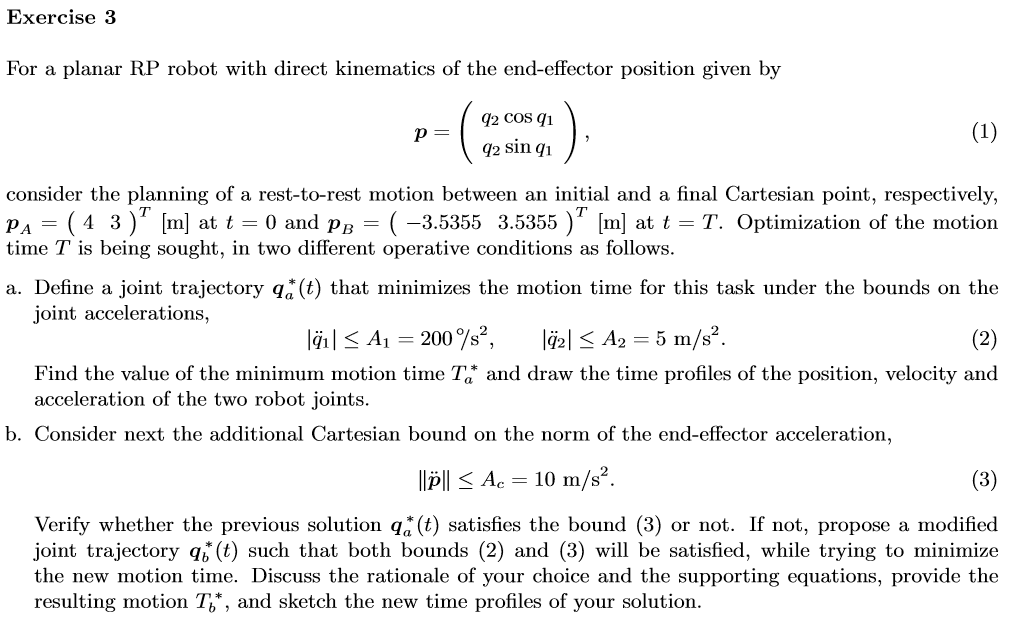

q = sym('q',[2,1],'real')
p = [q(2)*cos(q(1)); q(2)*sin(q(1))]
pa = [4;3];
pb = [-3.5355 ;3.5355];
qa_sol=solve(p == pa, q);
[qa_array_,qa_names_,qa_]=solvetoarray(qa_sol,q);
% [q_a1 q_a2 ] = solve(p == pa, q);
eval([qa_])
qb_sol = solve(p == pb, q);
[qb_array_,qb_names_,qb_]=solvetoarray(qb_sol,q);

eval([qb_])


%%converting in degrees
qa_(1,:)=180/pi*qa_(1,:);
qb_(1,:)=180/pi*qb_(1,:);
%We choose the solution with positive q2
pick = 2;
qA = eval([qa_(:,pick)])
qB = eval([qb_(:,pick)])
deltaq=qB-qA;

### Bang-bang profile

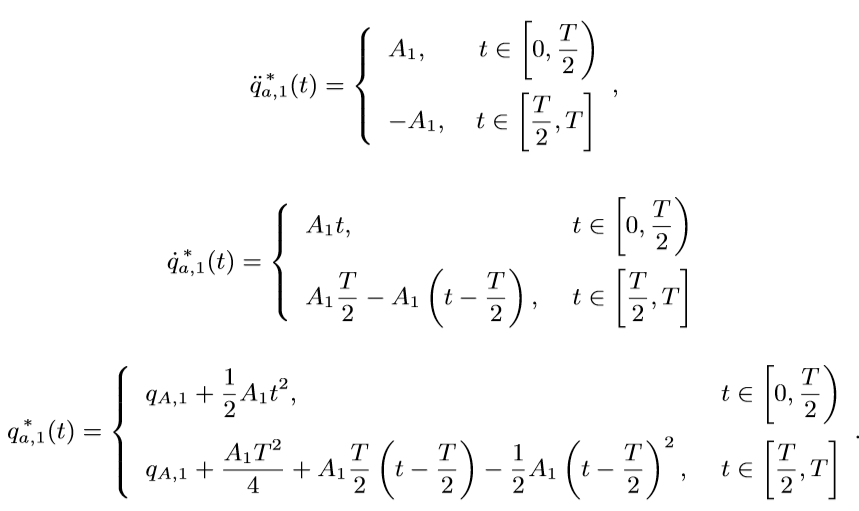

syms A1 T t t2nd

A1_=200%57.7799%
[qa_piece1,T_,V1peak_] = BangBangPRofile(qA(1),qB(1), A1_)%A1_)
deltaq
L_Criterio=V1peak_^2/A1_
%%in this case is no needed a cost midle part only bnag bang

fplot(qa_piece1(1),[0,T_])
grid on
fplot(qa_piece1(2),[0,T_])
grid on
fplot(qa_piece1(3),[0,T_]) % There's a difference in the result.
grid on



## q2

% A2_=5%57.7799%
% [qa_piece2,T2_,V2peak_] = BangBangPRofile(qA(2),qB(2), A2_)%A1_)
% deltaq
% L_Criterio2=V1peak_^2/A2_
% %%in this case is no needed a cost midle part only bnag bang

% fplot(qa_piece2(1),[0,T_])
% grid on
% fplot(qa_piece2(2),[0,T_])
% grid on
% fplot(qa_piece2(3),[0,T_]) % There's a difference in the result.
% grid on

## rescaling to the max velocity q1


q = sym('q',[2,1],'real')
q_d1 = sym('q%d_d1',[2,1],'real')
q_d1_=[V1peak_*pi/180,0]';
q_d2 = sym('q%d_d2',[2,1],'real')
q_d2_=[A1_*pi/180,0]';
syms q1(t) q2(t) 
t=sym('t','real')
assumeAlso(q1(t),'real')
assumeAlso(q2(t),'real')

p1(t) = [q2*cos(q1); q2*sin(q1)]

p1_d1(t)=diff(p1)
p1_d2(t)=diff(p1_d1)

p1_d2_=shortdiff(p1_d2(t),{q1;q2},t,false,2)
%  [Rz, R_set] = getRotMatProduct('Z',0,[ q(1)]);
% 
% Rz2=Rz(1:end-1,1:end-1)
% p1_d2rot=simplify(norm(simplify(Rz2'*p1_d2_)))
% PmaxAcel_=vpa(subs(p1_d2rot,[q(2);q_d1;q_d2],[qB(2);q_d1_;q_d2_]),4)
p1_d2=simplify(norm(simplify(p1_d2_)))
PmaxAcel2_=vpa(subs(p1_d2,[q(2);q_d1;q_d2],[qB(2);q_d1_;q_d2_]),4) % sin la estupida matriz de rotación


## finding k constant

k=sym('k','real')
Pmaxacel=10
% PmaxAcel3sym=simplify(subs(p1_d2,[q_d1;q_d2],[[q_d1(1)/k;q_d1_(2)];[q_d2(1)/(k^2);q_d2_(2)]]))
% PmaxAcel3sym_=vpa(subs(PmaxAcel3sym,[q(2);q_d1;q_d2],[qB(2);q_d1_;q_d2_]),4)


%% solo se remplaza valores en el rotacional en el otro no se puede xd
PmaxAcel3=vpa(subs(p1_d2,[q(2);q_d1;q_d2],[qA(2);[q_d1_(1)/k;q_d1_(2)];[q_d2_(1)/(k^2);q_d2_(2)]]),4)
k_=solve(PmaxAcel3==Pmaxacel)
 %new Ta
 
T1_=max(k_)*(T_)
% New A1
A1_2=A1_/(k_(2)^2)%abs(deltaq(1))*4/(T1_^2)

## arci aproach






% % % syms q0 q1 v0 v1 t T a b c tao dq 
% % % 
% % % % Declare equation system for joint space trajectory
% % % 
% % % eq(1) = a+b+c == 1;
% % % eq(2) = c == v0*T/dq;
% % % eq(3) = 3*a+2*b+c == v1*T/dq;
% % % eq.';
% % % [as,bs,cs]=solve(eq.',[a b c])
% % % 
% % % qd = q0 + dq*(as*tao^3 + bs*tao^2 + cs*tao)
% % % 
% % % qa = subs(qd,[dq tao],[q1-q0 t/T])
% % % qa = subs(qa,[v0 v1],[0 0])
% % % 
% % % %Initial conditions
% % % % w is omega, for angular velocity
% % % % acc is angular acceleration
% % % w = diff(qa,t)
% % % acc = diff(w,t)
% % % 
% % % %w0 = subs(w,t,0)
% % % %wT = subs(w,t,T)
% % % 
% % % %acc0 = subs(acc,t,0)
% % % %jerk = diff(acc,t)

% % % %Evaluate the expression with the initial and final joint values
% % % %The f subscript is used to differenciate a from the point. q_a = f
% % % 
% % % acc_f = subs(acc,[q0 q1],[qA(1) qB(1)])
% % % %Derivate to get the maximum point of accelerarion, and apply the boundary
% % % jerk_f = diff(acc_f,t)
% % % solve(jerk_f == 0,t)
% % % 
% % % %q0 = 

% % % 